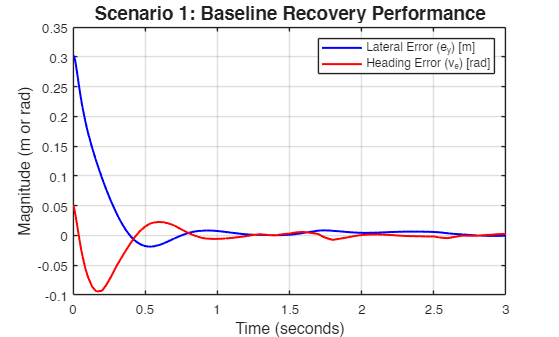

% Plotting Script for Scenario 1: Baseline Recovery

% Create a new figure with a white background
figure('Color', 'w'); 

% Plot Lateral Error (Yellow line from your scope)
plot(out.tout, out.e_y, 'b', 'LineWidth', 1.5); 
hold on;

% Plot Heading Error (Blue line from your scope)
plot(out.tout, out.v_e, 'r', 'LineWidth', 1.5); 

% Formatting the graph for the report
grid on;
title('Scenario 1: Baseline Recovery Performance', 'FontSize', 14);
xlabel('Time (seconds)', 'FontSize', 12);
ylabel('Magnitude (m or rad)', 'FontSize', 12);
legend('Lateral Error (e_y) [m]', 'Heading Error (v_e) [rad]', 'Location', 'northeast');

% Zoom in on the critical first second to show the full recovery curve
xlim([0 3]); 
ylim([-0.1 0.35]); 

hold off;

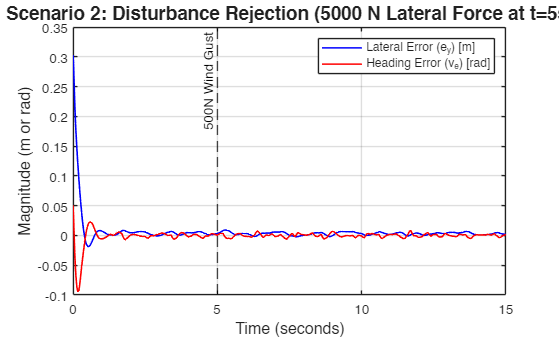

% Plotting Script for Scenario 2: Disturbance Rejection (Crosswind)

figure('Color', 'w'); 

% Plot Lateral Error (Yellow line from your scope)
plot(out.tout, out.e_y, 'b', 'LineWidth', 1.2); 
hold on;

% Plot Heading Error (Blue line from your scope)
plot(out.tout, out.v_e, 'r', 'LineWidth', 1.2); 

% Add a vertical line to indicate when the wind hits
xline(5, '--k', '500N Wind Gust', 'LabelHorizontalAlignment', 'left', 'FontSize', 10);

% Formatting the graph for the report
grid on;
title('Scenario 2: Disturbance Rejection (5000 N Lateral Force at t=5s)', 'FontSize', 14);
xlabel('Time (seconds)', 'FontSize', 12);
ylabel('Magnitude (m or rad)', 'FontSize', 12);
legend('Lateral Error (e_y) [m]', 'Heading Error (v_e) [rad]', 'Location', 'northeast');

% Set axis limits to show the full 15-second run
xlim([0 15]); 

hold off;

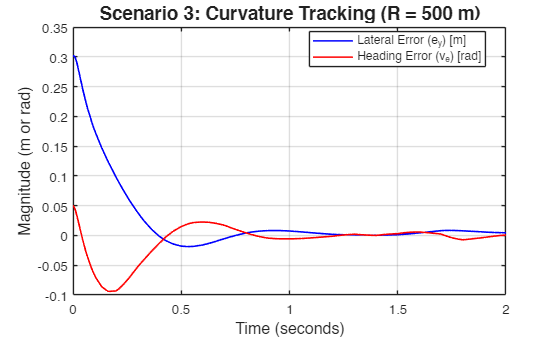

% Plotting Script for Scenario 3: Curvature Tracking

figure('Color', 'w'); 

% Plot Lateral Error
plot(out.tout, out.e_y, 'b', 'LineWidth', 1.2); 
hold on;

% Plot Heading Error
plot(out.tout, out.v_e, 'r', 'LineWidth', 1.2); 

% Formatting the graph for the report
grid on;
title('Scenario 3: Curvature Tracking (R = 500 m)', 'FontSize', 14);
xlabel('Time (seconds)', 'FontSize', 12);
ylabel('Magnitude (m or rad)', 'FontSize', 12);
legend('Lateral Error (e_y) [m]', 'Heading Error (v_e) [rad]', 'Location', 'best');

% Set axis limits
xlim([0 2]); 

hold off;